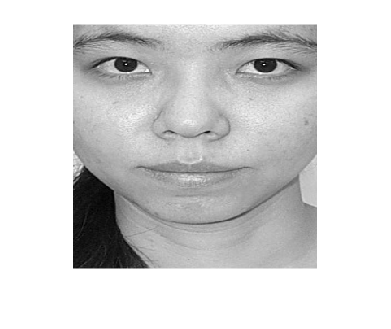

clear
%read all images, normalize and create eigenfaces
target_size = [300,300];
[DataMatrix, ImageFiles] = normalize_all_images("../db/DB1/", target_size);

[meanface, eigenVectors, weights] = compute_eigenfaces(DataMatrix,target_size);

img = imread("..\db\DB1\db1_16.jpg");
id = isPersonInSet(img, meanface, eigenVectors, target_size);
id

id = 12

% id = tnm034(img)